clear;close;clc;


## equations


equations = [
    "Dram = mdot_0 * V_0"
    "Fn = (mdot_0 + mdot_f) * V_9 - mdot_0 * V_0 + (p_9-p_0)*A_9"
    "Fg = (mdot_0+mdot_f)*V_9 - mdot_0 * V_0"
    "Fn = Fg - Dram"
    "TSFC = mdot_f / Fn" %no after burner
    %"TSFC = (mdot_f + mdot_f_AB) / Fn" %for afterburner 
    "TSFC = f / (Fn/mdot_0)"
    "eta_th = DeltaKEdot / pth"
    "pth = mdot_f * Qr + mdot_f_AB * Qr_AB"
    "DeltaKEdot = (mdot_0 + mdot_f + mdot_f_AB) * V_9^2 / 2 - mdot_0 * V_0^2 /2"
    "eta_p = Fn * V_0 / DeltaKEdot"
    "eta_p = 2/(1+V_9/V_0)"
    "f_AB = (1+f)*(ht_7-ht_5) / (Qr_AB * eta_AB - ht_7)"
    "pt_7 = pi_AB * pt_5"
    "eta_p = (Fn/mdot_0)*V0 / ((1+f+f_AB)*V_9^2/2 - v_0^2/2)"
    "Is = Fn/(mdot_f*g_0)"
    "eta_o = (Fn/mdot_0)*V_0 / (f*Qr)"
    "eta_o = (V_0/Qr) / TSFC"
    %"pi_n = ((pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - eta_n * ((pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - 1))^(-gamma/(gamma-1))" % turbojet no after burner
    "pi_n = ((pi_AB*pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - eta_n * ((pi_AB*pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - 1))^(-gamma/(gamma-1))" % turbojet with after burner (I belive assumes const gamma)
    "pi_d = pt_0 / pt_2"
    "eta_d = ((pt_2/p_0)^((gamma_c-1)/gamma_c) -1) / (M_0^2*(gamma_c-1)/2)" % unsure which gamma to use
    "pi_c = pt_3/pt_2"
    "pi_c_lp = pt_2_5/+pt_2"
    "pi_c_hp = pt_3/pt_2_5"
    "pi_c = pi_c_lp*pi_c_hp"
    "pi_b = pt_4 / pt_3"
    "pi_AB = pt_7 / pt_5"
    "pi_n = pt_9 / pt_7"
    "pi_t = pt_5 / pt_4"
    "pi_r = pt_0 / P_0"
    "pi_r = (1+(gamma_c-1)/2*M_0^2)^(gamma_c/(gamma_c-1))"
    "tau_r = Tt_0 / T_0"
    "tau_r = 1 + (gamma_c-1)/2 *M_0^2"
    "tau_d = Tt_2/Tt_0"
    "tau_lambda = cp_4*Tt_4 / cp_0*T_0"
    "eta_b = Qr_actual / Qr_ideal"
    "eta_AB = Qr_AB_actual / Qr_AB_ideal"
    "tau_lambda_AB = cp_AB*Tt_7 / cp_0*T_0"
    "tau_n = Tt_9 / Tt_7"
    "tau_c = Tt_3 / Tt_2"
    "tau_c = tau_c_lp*tau_c_hp"
    "tau_c_lp = Tt_2 / Tt_2_5"
    "tau_c_hp = Tt_3 / Tt_2_5"
    "tau_t = Tt_5 / Tt_4"
    %"pi_c_optimum = ((tau_lambda)^.5 / (1+(gamma-1)/2*M_0^2))^(gamma/(gamma-1))" %turbo jet no after burner
    "pi_c_optimum = ((tau_r + tau_lambda) / (2*tau_r))^(gamma/(gamma-1))" %after burning tubo jet
    "eta_d = (ht_2s/h_0 - 1) / (ht_2/h_0 - 1)"
    "eta_d = (Tt_2s/T_0 - 1) / (ht_0/h_0 - 1)"
    "eta_d = ((pt_2/p_0)^((gamma_c-1)/gamma_c) - 1) / (tau_r - 1)"
    %"pi_d = ((1 + eta_d * (gamma_c-1)/2 * M_0^2) / (1 + (gamma_c-1)/2 * M_0^2))^(gamma_c/(gamma_c-1))"
    "tau_c = pi_c^((gamma-1)/(gamma*e_c))"
    "P_r = mdot_t * (ht_2-ht_3)"
    "eta_carnot = 1 - T_min/T_max"
    "eta_carnot = 1 - Tt_min/Tt_max"

    %power relations
    "P_fan = mdot_fan *cp_fan * (Tt_2 - Tt13)"
    "P_compressor = mdot_core *cp_core * (Tt_2 - Tt3)"

]

equations = 53×1 string array
    "Dram = mdot_0 * V_0"
    "Fn = (mdot_0 + mdot_f) * V_9 - mdot_0 * V_0 + (p_9-p_0)*A_9"
    "Fg = (mdot_0+mdot_f)*V_9 - mdot_0 * V_0"
    "Fn = Fg - Dram"
    "TSFC = mdot_f / Fn"
    "TSFC = f / (Fn/mdot_0)"
    "eta_th = DeltaKEdot / pth"
    "pth = mdot_f * Qr + mdot_f_AB * Qr_AB"
    "DeltaKEdot = (mdot_0 + mdot_f + mdot_f_AB) * V_9^2 / 2 - mdot_0 * V_0^2 /2"
    "eta_p = Fn * V_0 / DeltaKEdot"
    "eta_p = 2/(1+V_9/V_0)"
    "f_AB = (1+f)*(ht_7-ht_5) / (Qr_AB * eta_AB - ht_7)"
    "pt_7 = pi_AB * pt_5"
    "eta_p = (Fn/mdot_0)*V0 / ((1+f+f_AB)*V_9^2/2 - v_0^2/2)"
    "Is = Fn/(mdot_f*g_0)"
    "eta_o = (Fn/mdot_0)*V_0 / (f*Qr)"
    "eta_o = (V_0/Qr) / TSFC"
    "pi_n = ((pi_AB*pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - eta_n * ((pi_AB*pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - 1))^(-gamma/(gamma-1))"
    "pi_d = pt_0 / pt_2"
    "eta_d = ((pt_2/p_0)^((gamma_c-1)/gamma_c) -1) / (M_0^2*(gamma_c-1)/2)"
    "pi_c = pt_3/pt_2"
   


%maybe implement 3 gammas cold medium and hot

%assumptions
equations = [ equations
    "F= Fn" %not sure about this one
    
    %const gamma
    %"gamma_c = gamma" % const gamma
    %"gamma_t = gamma" % const gamma
    %"gamma_AB = gamma" % const gamma

    %3 gammas hot cold and very hot
    "gamma_0 = gamma_c"
    "gamma_1 = gamma_c"
    "gamma_2 = gamma_c"
    "gamma_3 = gamma_c"

    "gamma_4 = gamma_t"
    "gamma_5 = gamma_t"
    
    "gamma_6 = gamma_AB"
    "gamma_7 = gamma_AB"
    "gamma_8 = gamma_AB"
    "gamma_9 = gamma_AB"

    %accompanying specific heats
    "cp_0 = cp_c"
    "cp_1 = cp_c"
    "cp_2 = cp_c"
    "cp_3 = cp_c"

    "cp_4 = cp_t"
    "cp_5 = cp_t"
    
    "cp_6 = cp_t"
    "cp_7 = cp_AB"
    "cp_8 = cp_AB"
    "cp_9 = cp_AB"

    %after burning turbo jet
    "tau_d = 1"
    "tau_n = 1"
    
    % max temperature at back of engine and min T at compressor face
    "Tt_max = Tt_9"
    "Tt_min = Tt_2"

    %normal shock in inlet (critical mode)
    "M_2 = ( ((gamma_c-1)*M_0^2+2) / (2*gamma_c*M_0^2-(gamma_c-1)) )^.5" %normal shock in inlet (critical mode) (use cold gamma_c)
    "rho_2 / rho_0 = ((gamma_c+1)*M_0^2) / (2 + (gamma_c-1)*M_0^2)"
    "p_2 / p_0 = 1 + 2*gamma_c/(gamma_c+1) * (M_0^2-1)"
    "T_2 / T_0 = (p_2 / p_0) / (rho_2 / rho_0)"
    "pt_2 / pt_0 = (((gamma_c+1)*M_0^2) / ((gamma_c-1)*M_0^2+2))^(gamma_c/(gamma_c-1)) * ((gamma_c+1) / (2*gamma_c*M_0^2-(gamma_c-1)))^(1/(gamma_c-1))"
    "Tt2 = Tt0"

    "p_9 = p_0" % no pressure 
]

equations = 85×1 string array
    "Dram = mdot_0 * V_0"
    "Fn = (mdot_0 + mdot_f) * V_9 - mdot_0 * V_0 + (p_9-p_0)*A_9"
    "Fg = (mdot_0+mdot_f)*V_9 - mdot_0 * V_0"
    "Fn = Fg - Dram"
    "TSFC = mdot_f / Fn"
    "TSFC = f / (Fn/mdot_0)"
    "eta_th = DeltaKEdot / pth"
    "pth = mdot_f * Qr + mdot_f_AB * Qr_AB"
    "DeltaKEdot = (mdot_0 + mdot_f + mdot_f_AB) * V_9^2 / 2 - mdot_0 * V_0^2 /2"
    "eta_p = Fn * V_0 / DeltaKEdot"
    "eta_p = 2/(1+V_9/V_0)"
    "f_AB = (1+f)*(ht_7-ht_5) / (Qr_AB * eta_AB - ht_7)"
    "pt_7 = pi_AB * pt_5"
    "eta_p = (Fn/mdot_0)*V0 / ((1+f+f_AB)*V_9^2/2 - v_0^2/2)"
    "Is = Fn/(mdot_f*g_0)"
    "eta_o = (Fn/mdot_0)*V_0 / (f*Qr)"
    "eta_o = (V_0/Qr) / TSFC"
    "pi_n = ((pi_AB*pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - eta_n * ((pi_AB*pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - 1))^(-gamma/(gamma-1))"
    "pi_d = pt_0 / pt_2"
    "eta_d = ((pt_2/p_0)^((gamma_c-1)/gamma_c) -1) / (M_0^2*(gamma_c-1)/2)"
    "pi_c = pt_3/pt_2"
   


% add repeated equations
repEqs = [
    %sonic
    "M_st = V_st / a_st"
    "a_st = (gamma_st*R*T_st)^.5"

    % isentropic
    "pt_st / p_st = (1 + (gamma_st-1)/2 * M_st^2)^(gamma_st/(gamma_st-1))" % isentropic
    "rhot_st / rho_st = (1 + (gamma_st-1)/2 * M_st^2)^(1/(gamma_st-1))" % isentropic
    "Tt_st / T_st = (1 + (gamma_st-1)/2 * M_st^2)^1" % isentropic
    
    %total enthalpy and total entropy
    "ht_st = h_st + V_st^2/2"
    "st_st = s_st"

    % see chapter 2 for more, general equations

    % caloricly perfect
    "Tt_st = T_st + V_st^2/(2*cp_st)"


    %ideal gas
    "p_st = rho_st * R * T_st"
    "cp_st = cv_st + R"

    % constant specific heats
    "cp_st = gamma_st * R / (gamma_st - 1)"
    "cv_st = R / (gamma_st - 1)"
];

% assumpitons
% repEqs = [ repEqs
%     %"gamma_st = gamma" % const gamma
% ]

for i = 1:length(repEqs) % prepare for application to each station
    repEqs(i) = replace(repEqs(i),"_st","_%1$d");
end

% apply to each station
for i = 1:length(repEqs)
    repEq = repEqs(i);
    for station = 0:9
        eq = sprintf(repEq, station);
        equations(end+1) = eq;
    end
end


%equations that exist for all stages
stageRepeatedEquations = [
    "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"
    ]

stageRepeatedEquations = "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"


engineStages = ["d","f","c","fn","n","b","AB","t"]; % list of all engine stages

% add stage repeated equations to the list of equations
for i = 1:length(stageRepeatedEquations) 
    equation = stageRepeatedEquations(i); % get the equation to repeat
    stageRepeatedEquations(i) = replace(repEqs(i),"_x","_%1$s"); %format to be easy to repeat
    for stage = engineStages() % repeate equation for all stations
        equations(end+1) = sprintf(equation,stage); % substitue the stage into the equation and add to our list fo equations
    end
end

## Relations


relations = Relation.empty([0,length(equations)]); % declare list of relations
for i = 1:length(equations) % populate list of relations
    equations(i)
    relations(i) = Relation(equations(i));
end

ans = "Dram = mdot_0 * V_0"

ans = "Fn = (mdot_0 + mdot_f) * V_9 - mdot_0 * V_0 + (p_9-p_0)*A_9"

ans = "Fg = (mdot_0+mdot_f)*V_9 - mdot_0 * V_0"

ans = "Fn = Fg - Dram"

ans = "TSFC = mdot_f / Fn"

ans = "TSFC = f / (Fn/mdot_0)"

ans = "eta_th = DeltaKEdot / pth"

ans = "pth = mdot_f * Qr + mdot_f_AB * Qr_AB"

ans = "DeltaKEdot = (mdot_0 + mdot_f + mdot_f_AB) * V_9^2 / 2 - mdot_0 * V_0^2 /2"

ans = "eta_p = Fn * V_0 / DeltaKEdot"

ans = "eta_p = 2/(1+V_9/V_0)"

ans = "f_AB = (1+f)*(ht_7-ht_5) / (Qr_AB * eta_AB - ht_7)"

ans = "pt_7 = pi_AB * pt_5"

ans = "eta_p = (Fn/mdot_0)*V0 / ((1+f+f_AB)*V_9^2/2 - v_0^2/2)"

ans = "Is = Fn/(mdot_f*g_0)"

ans = "eta_o = (Fn/mdot_0)*V_0 / (f*Qr)"

ans = "eta_o = (V_0/Qr) / TSFC"

ans = "pi_n = ((pi_AB*pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - eta_n * ((pi_AB*pi_t*pi_b*pi_c*pi_d*pi_r*p_0/p_9)^((gamma-1)/gamma) - 1))^(-gamma/(gamma-1))"

ans = "pi_d = pt_0 / pt_2"

ans = "eta_d = ((pt_2/p_0)^((gamma_c-1)/gamma_c) -1) / (M_0^2*(gamma_c-1)/2)"

ans = "pi_c = pt_3/pt_2"

ans = "pi_c_lp = pt_2_5/+pt_2"

ans = "pi_c_hp = pt_3/pt_2_5"

ans = "pi_c = pi_c_lp*pi_c_hp"

ans = "pi_b = pt_4 / pt_3"

ans = "pi_AB = pt_7 / pt_5"

ans = "pi_n = pt_9 / pt_7"

ans = "pi_t = pt_5 / pt_4"

ans = "pi_r = pt_0 / P_0"

ans = "pi_r = (1+(gamma_c-1)/2*M_0^2)^(gamma_c/(gamma_c-1))"

ans = "tau_r = Tt_0 / T_0"

ans = "tau_r = 1 + (gamma_c-1)/2 *M_0^2"

ans = "tau_d = Tt_2/Tt_0"

ans = "tau_lambda = cp_4*Tt_4 / cp_0*T_0"

ans = "eta_b = Qr_actual / Qr_ideal"

ans = "eta_AB = Qr_AB_actual / Qr_AB_ideal"

ans = "tau_lambda_AB = cp_AB*Tt_7 / cp_0*T_0"

ans = "tau_n = Tt_9 / Tt_7"

ans = "tau_c = Tt_3 / Tt_2"

ans = "tau_c = tau_c_lp*tau_c_hp"

ans = "tau_c_lp = Tt_2 / Tt_2_5"

ans = "tau_c_hp = Tt_3 / Tt_2_5"

ans = "tau_t = Tt_5 / Tt_4"

ans = "pi_c_optimum = ((tau_r + tau_lambda) / (2*tau_r))^(gamma/(gamma-1))"

ans = "eta_d = (ht_2s/h_0 - 1) / (ht_2/h_0 - 1)"

ans = "eta_d = (Tt_2s/T_0 - 1) / (ht_0/h_0 - 1)"

ans = "eta_d = ((pt_2/p_0)^((gamma_c-1)/gamma_c) - 1) / (tau_r - 1)"

ans = "tau_c = pi_c^((gamma-1)/(gamma*e_c))"

ans = "P_r = mdot_t * (ht_2-ht_3)"

ans = "eta_carnot = 1 - T_min/T_max"

ans = "eta_carnot = 1 - Tt_min/Tt_max"

ans = "P_fan = mdot_fan *cp_fan * (Tt_2 - Tt13)"

ans = "P_compressor = mdot_core *cp_core * (Tt_2 - Tt3)"

ans = "F= Fn"

ans = "gamma_0 = gamma_c"

ans = "gamma_1 = gamma_c"

ans = "gamma_2 = gamma_c"

ans = "gamma_3 = gamma_c"

ans = "gamma_4 = gamma_t"

ans = "gamma_5 = gamma_t"

ans = "gamma_6 = gamma_AB"

ans = "gamma_7 = gamma_AB"

ans = "gamma_8 = gamma_AB"

ans = "gamma_9 = gamma_AB"

ans = "cp_0 = cp_c"

ans = "cp_1 = cp_c"

ans = "cp_2 = cp_c"

ans = "cp_3 = cp_c"

ans = "cp_4 = cp_t"

ans = "cp_5 = cp_t"

ans = "cp_6 = cp_t"

ans = "cp_7 = cp_AB"

ans = "cp_8 = cp_AB"

ans = "cp_9 = cp_AB"

ans = "tau_d = 1"

ans = "tau_n = 1"

ans = "Tt_max = Tt_9"

ans = "Tt_min = Tt_2"

ans = "M_2 = ( ((gamma_c-1)*M_0^2+2) / (2*gamma_c*M_0^2-(gamma_c-1)) )^.5"

ans = "rho_2 / rho_0 = ((gamma_c+1)*M_0^2) / (2 + (gamma_c-1)*M_0^2)"

ans = "p_2 / p_0 = 1 + 2*gamma_c/(gamma_c+1) * (M_0^2-1)"

ans = "T_2 / T_0 = (p_2 / p_0) / (rho_2 / rho_0)"

ans = "pt_2 / pt_0 = (((gamma_c+1)*M_0^2) / ((gamma_c-1)*M_0^2+2))^(gamma_c/(gamma_c-1)) * ((gamma_c+1) / (2*gamma_c*M_0^2-(gamma_c-1)))^(1/(gamma_c-1))"

ans = "Tt2 = Tt0"

ans = "p_9 = p_0"

ans = "M_0 = V_0 / a_0"

ans = "M_1 = V_1 / a_1"

ans = "M_2 = V_2 / a_2"

ans = "M_3 = V_3 / a_3"

ans = "M_4 = V_4 / a_4"

ans = "M_5 = V_5 / a_5"

ans = "M_6 = V_6 / a_6"

ans = "M_7 = V_7 / a_7"

ans = "M_8 = V_8 / a_8"

ans = "M_9 = V_9 / a_9"

ans = "a_0 = (gamma_0*R*T_0)^.5"

ans = "a_1 = (gamma_1*R*T_1)^.5"

ans = "a_2 = (gamma_2*R*T_2)^.5"

ans = "a_3 = (gamma_3*R*T_3)^.5"

ans = "a_4 = (gamma_4*R*T_4)^.5"

ans = "a_5 = (gamma_5*R*T_5)^.5"

ans = "a_6 = (gamma_6*R*T_6)^.5"

ans = "a_7 = (gamma_7*R*T_7)^.5"

ans = "a_8 = (gamma_8*R*T_8)^.5"

ans = "a_9 = (gamma_9*R*T_9)^.5"

ans = "pt_0 / p_0 = (1 + (gamma_0-1)/2 * M_0^2)^(gamma_0/(gamma_0-1))"

ans = "pt_1 / p_1 = (1 + (gamma_1-1)/2 * M_1^2)^(gamma_1/(gamma_1-1))"

ans = "pt_2 / p_2 = (1 + (gamma_2-1)/2 * M_2^2)^(gamma_2/(gamma_2-1))"

ans = "pt_3 / p_3 = (1 + (gamma_3-1)/2 * M_3^2)^(gamma_3/(gamma_3-1))"

ans = "pt_4 / p_4 = (1 + (gamma_4-1)/2 * M_4^2)^(gamma_4/(gamma_4-1))"

ans = "pt_5 / p_5 = (1 + (gamma_5-1)/2 * M_5^2)^(gamma_5/(gamma_5-1))"

ans = "pt_6 / p_6 = (1 + (gamma_6-1)/2 * M_6^2)^(gamma_6/(gamma_6-1))"

ans = "pt_7 / p_7 = (1 + (gamma_7-1)/2 * M_7^2)^(gamma_7/(gamma_7-1))"

ans = "pt_8 / p_8 = (1 + (gamma_8-1)/2 * M_8^2)^(gamma_8/(gamma_8-1))"

ans = "pt_9 / p_9 = (1 + (gamma_9-1)/2 * M_9^2)^(gamma_9/(gamma_9-1))"

ans = "rhot_0 / rho_0 = (1 + (gamma_0-1)/2 * M_0^2)^(1/(gamma_0-1))"

ans = "rhot_1 / rho_1 = (1 + (gamma_1-1)/2 * M_1^2)^(1/(gamma_1-1))"

ans = "rhot_2 / rho_2 = (1 + (gamma_2-1)/2 * M_2^2)^(1/(gamma_2-1))"

ans = "rhot_3 / rho_3 = (1 + (gamma_3-1)/2 * M_3^2)^(1/(gamma_3-1))"

ans = "rhot_4 / rho_4 = (1 + (gamma_4-1)/2 * M_4^2)^(1/(gamma_4-1))"

ans = "rhot_5 / rho_5 = (1 + (gamma_5-1)/2 * M_5^2)^(1/(gamma_5-1))"

ans = "rhot_6 / rho_6 = (1 + (gamma_6-1)/2 * M_6^2)^(1/(gamma_6-1))"

ans = "rhot_7 / rho_7 = (1 + (gamma_7-1)/2 * M_7^2)^(1/(gamma_7-1))"

ans = "rhot_8 / rho_8 = (1 + (gamma_8-1)/2 * M_8^2)^(1/(gamma_8-1))"

ans = "rhot_9 / rho_9 = (1 + (gamma_9-1)/2 * M_9^2)^(1/(gamma_9-1))"

ans = "Tt_0 / T_0 = (1 + (gamma_0-1)/2 * M_0^2)^1"

ans = "Tt_1 / T_1 = (1 + (gamma_1-1)/2 * M_1^2)^1"

ans = "Tt_2 / T_2 = (1 + (gamma_2-1)/2 * M_2^2)^1"

ans = "Tt_3 / T_3 = (1 + (gamma_3-1)/2 * M_3^2)^1"

ans = "Tt_4 / T_4 = (1 + (gamma_4-1)/2 * M_4^2)^1"

ans = "Tt_5 / T_5 = (1 + (gamma_5-1)/2 * M_5^2)^1"

ans = "Tt_6 / T_6 = (1 + (gamma_6-1)/2 * M_6^2)^1"

ans = "Tt_7 / T_7 = (1 + (gamma_7-1)/2 * M_7^2)^1"

ans = "Tt_8 / T_8 = (1 + (gamma_8-1)/2 * M_8^2)^1"

ans = "Tt_9 / T_9 = (1 + (gamma_9-1)/2 * M_9^2)^1"

ans = "ht_0 = h_0 + V_0^2/2"

ans = "ht_1 = h_1 + V_1^2/2"

ans = "ht_2 = h_2 + V_2^2/2"

ans = "ht_3 = h_3 + V_3^2/2"

ans = "ht_4 = h_4 + V_4^2/2"

ans = "ht_5 = h_5 + V_5^2/2"

ans = "ht_6 = h_6 + V_6^2/2"

ans = "ht_7 = h_7 + V_7^2/2"

ans = "ht_8 = h_8 + V_8^2/2"

ans = "ht_9 = h_9 + V_9^2/2"

ans = "st_0 = s_0"

ans = "st_1 = s_1"

ans = "st_2 = s_2"

ans = "st_3 = s_3"

ans = "st_4 = s_4"

ans = "st_5 = s_5"

ans = "st_6 = s_6"

ans = "st_7 = s_7"

ans = "st_8 = s_8"

ans = "st_9 = s_9"

ans = "Tt_0 = T_0 + V_0^2/(2*cp_0)"

ans = "Tt_1 = T_1 + V_1^2/(2*cp_1)"

ans = "Tt_2 = T_2 + V_2^2/(2*cp_2)"

ans = "Tt_3 = T_3 + V_3^2/(2*cp_3)"

ans = "Tt_4 = T_4 + V_4^2/(2*cp_4)"

ans = "Tt_5 = T_5 + V_5^2/(2*cp_5)"

ans = "Tt_6 = T_6 + V_6^2/(2*cp_6)"

ans = "Tt_7 = T_7 + V_7^2/(2*cp_7)"

ans = "Tt_8 = T_8 + V_8^2/(2*cp_8)"

ans = "Tt_9 = T_9 + V_9^2/(2*cp_9)"

ans = "p_0 = rho_0 * R * T_0"

ans = "p_1 = rho_1 * R * T_1"

ans = "p_2 = rho_2 * R * T_2"

ans = "p_3 = rho_3 * R * T_3"

ans = "p_4 = rho_4 * R * T_4"

ans = "p_5 = rho_5 * R * T_5"

ans = "p_6 = rho_6 * R * T_6"

ans = "p_7 = rho_7 * R * T_7"

ans = "p_8 = rho_8 * R * T_8"

ans = "p_9 = rho_9 * R * T_9"

ans = "cp_0 = cv_0 + R"

ans = "cp_1 = cv_1 + R"

ans = "cp_2 = cv_2 + R"

ans = "cp_3 = cv_3 + R"

ans = "cp_4 = cv_4 + R"

ans = "cp_5 = cv_5 + R"

ans = "cp_6 = cv_6 + R"

ans = "cp_7 = cv_7 + R"

ans = "cp_8 = cv_8 + R"

ans = "cp_9 = cv_9 + R"

ans = "cp_0 = gamma_0 * R / (gamma_0 - 1)"

ans = "cp_1 = gamma_1 * R / (gamma_1 - 1)"

ans = "cp_2 = gamma_2 * R / (gamma_2 - 1)"

ans = "cp_3 = gamma_3 * R / (gamma_3 - 1)"

ans = "cp_4 = gamma_4 * R / (gamma_4 - 1)"

ans = "cp_5 = gamma_5 * R / (gamma_5 - 1)"

ans = "cp_6 = gamma_6 * R / (gamma_6 - 1)"

ans = "cp_7 = gamma_7 * R / (gamma_7 - 1)"

ans = "cp_8 = gamma_8 * R / (gamma_8 - 1)"

ans = "cp_9 = gamma_9 * R / (gamma_9 - 1)"

ans = "cv_0 = R / (gamma_0 - 1)"

ans = "cv_1 = R / (gamma_1 - 1)"

ans = "cv_2 = R / (gamma_2 - 1)"

ans = "cv_3 = R / (gamma_3 - 1)"

ans = "cv_4 = R / (gamma_4 - 1)"

ans = "cv_5 = R / (gamma_5 - 1)"

ans = "cv_6 = R / (gamma_6 - 1)"

ans = "cv_7 = R / (gamma_7 - 1)"

ans = "cv_8 = R / (gamma_8 - 1)"

ans = "cv_9 = R / (gamma_9 - 1)"

ans = "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"

ans = "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"

ans = "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"

ans = "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"

ans = "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"

ans = "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"

ans = "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"

ans = "tau_x = pi_x^((gamma_x-1)/(gamma_x*e_x))"

## knowns dictionary

knowns = dictionary % initialize dictionary

knowns =   dictionary with unset key and value types.



for rel = relations() %populate disctionary
    for var = rel.variables()
        knowns(var) = nan;
    end
end

## declare Knowns

%todo read from excel table
knowns("mdot_0") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ NaN
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
    "gam

knowns("M_0") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ NaN
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
    "gam

knowns("p_0") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ NaN
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
    "gam

knowns("T_0") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ NaN
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
    "gam

knowns("gamma") = 1.4

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ NaN
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
    "gam

knowns("R") = 287

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ NaN
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
    "gam

knowns("mdot_f") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ NaN
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
    "gam

knowns("Qr") = 4.326e7;
knowns("V_9") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
   

knowns("p_9") = nan   

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
   

% problem 6
knowns("eta_b") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
   

knowns("pi_b") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
   

knowns("pi_d") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
   

knowns("pi_c") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ NaN
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ NaN
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ NaN
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ NaN
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ NaN
   

%knowns("pi_c_lp") = 54/14.7
%knowns("pi_c_hp") = 167/54
%knowns("tau_c_lp") = (59+460)/(330+460)
%knowns("tau_c_hp") = (330+460)/(660+460)

knowns("pt_2") = 14.7 * (6.895e3);
knowns("pt_2_5") = 54 * (6.895e3);
knowns("pt_3") = 167 * (6.895e3);
knowns("pt_4") = 158 * (6.895e3);
knowns("pt_5") = 36 * (6.895e3);
knowns("Tt_2") = 59 + 460;
knowns("Tt_2_5") = 330 + 460;
knowns("Tt_3") = 660 + 460;
knowns("Tt_4") = 1570 + 460;
knowns("Tt_5") = 1013 + 460;
knowns("mdot_f") = 8520 * 1.26e-4;

%millitary power 
knowns("pt_9") = 33 * (6.895e3);
knowns("Tt_9") = 1013 + 460;
knowns("F") = 10.2e3 * 4.448;
knowns("mdot_f_AB") = 0;
knowns("mdot_0") = 164 * 0.454;



%maxiumum power 
%knowns("pt_9") = 31.9 * (6.895e3);
%knowns("Tt_9") = 2540 + 460;
%knowns("F") = 16e3 * 4.448;
%knowns("mdot_f_AB") = (33650-8520) * 1.26e-4;
%knowns("mdot_0") = 172 * 0.454;

%without after burner
%knowns("tau_t") =
%knowns("pi_t") =

% note i actually known the above values

knowns("e_c") = nan

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ NaN
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼


% assumptions
knowns("g_0") = 9.81

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ NaN
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"       


knowns("A_9") = 0 % not stricucly true but irrelevant in this context

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"         


%3 gammas hot cold and very hot
knowns("gamma_c") = 1.4

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"         

knowns("gamma_t") = 1.33

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"         

knowns("gamma_AB") = 1.3

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"         

%acompnying specific heats
knowns("cp_c") = 1004

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"         

knowns("cp_t") = 1156

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"         

knowns("cp_AB") = 1234

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"         


% no after burner
knowns("mdot_f_AB") = 0

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ NaN
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"         

knowns("Qr_AB") = 0

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ NaN
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ NaN
    "f"             ⟼ NaN
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ NaN
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ 0
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ NaN
    "g_0"           ⟼ 9.8100
    "eta_o"         ⟼ NaN
    "eta_n"         ⟼ 

## solve relations

hasChanged = true;

while hasChanged == true
    hasChanged = false;

    for rel = relations()
        n = 0;
        solveVar = "";
    
        for var = rel.variables()
            if(isnan(knowns(var)))
                n = n+1;
                solveVar = var;
            end
    
            if(n > 1) %end early if possilbe
                break
            end
        end
    
        if n == (1) % we can solve for the unknown
            % we have 1 unkonw and 1 equation thus can solve
            varMat = arrayfun( @(x) knowns(x), rel.variables);
            %disp(rel.solve(varMat))
            knowns(solveVar) = rel.solve(varMat);
            hasChanged = true;
            fprintf("solved %s = %g", solveVar, knowns(solveVar))
        end
    end
end

solved pth = 4.64405e+07solved pi_c = 11.3605solved pi_c_lp = 3.67347solved pi_c_hp = 3.09259solved pi_b = 0.946108solved pi_t = 0.227848solved tau_c = 2.158solved tau_c_lp = 0.656962solved tau_c_hp = 1.41772solved tau_t = 0.725616solved e_c = 0.902685solved Fn = 45369.6solved gamma_0 = 1.4solved gamma_1 = 1.4solved gamma_2 = 1.4solved gamma_3 = 1.4solved gamma_4 = 1.33solved gamma_5 = 1.33solved gamma_6 = 1.3solved gamma_7 = 1.3solved gamma_8 = 1.3solved gamma_9 = 1.3solved cp_0 = 1004solved cp_1 = 1004solved cp_2 = 1004solved cp_3 = 1004solved cp_4 = 1156solved cp_5 = 1156solved cp_6 = 1156solved cp_7 = 1234solved cp_8 = 1234solved cp_9 = 1234solved tau_d = 1solved tau_n = 1solved Tt_max = 1473solved Tt_min = 519solved cv_0 = 717solved cv_1 = 717solved cv_2 = 717solved cv_3 = 717solved cv_4 = 869solved cv_5 = 869solved cv_6 = 869solved cv_7 = 947solved cv_8 = 947solved cv_9 = 947solved TSFC = 2.36617e-05solved f = 0.0144182solved Is = 4308.1solved Tt_0 = 519solved Tt_7 = 1473solved e


knowns

knowns =   dictionary (string ⟼ double) with 244 entries:

    "Dram"          ⟼ NaN
    "V_0"           ⟼ NaN
    "mdot_0"        ⟼ 74.4560
    "A_9"           ⟼ 0
    "Fn"            ⟼ 4.5370e+04
    "V_9"           ⟼ NaN
    "mdot_f"        ⟼ 1.0735
    "p_0"           ⟼ NaN
    "p_9"           ⟼ NaN
    "Fg"            ⟼ NaN
    "TSFC"          ⟼ 2.3662e-05
    "f"             ⟼ 0.0144
    "DeltaKEdot"    ⟼ NaN
    "eta_th"        ⟼ NaN
    "pth"           ⟼ 4.6440e+07
    "Qr"            ⟼ 43260000
    "Qr_AB"         ⟼ 0
    "mdot_f_AB"     ⟼ 0
    "eta_p"         ⟼ NaN
    "eta_AB"        ⟼ NaN
    "f_AB"          ⟼ NaN
    "ht_5"          ⟼ NaN
    "ht_7"          ⟼ NaN
    "pi_AB"         ⟼ NaN
    "pt_5"          ⟼ 248220
    "pt_7"          ⟼ NaN
    "V0"            ⟼ NaN
    "v_0"           ⟼ NaN
    "Is"            ⟼ 4.3081e+03
    "g_0"           ⟼ 9.8100
    "eta_o"      

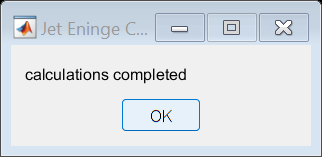

%fig = uifigure;
%gasConstInputPanel = uipanel(fig,"Title","Gas Constants")
%input = uieditfield(gasConstInputPanel,"numeric")
f = msgbox("calculations completed","Jet Eninge Calculator","modal");